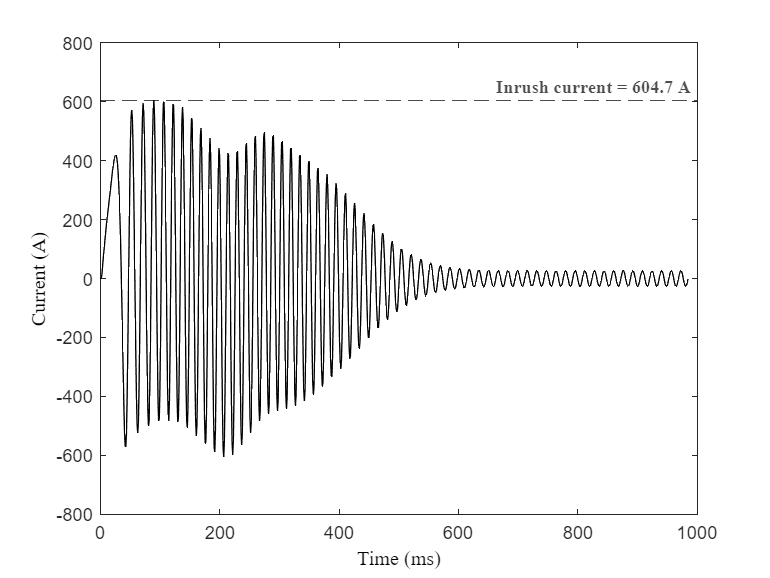

r_s = 0.087;        % Stator resistance (in Ohms)
r_r = 0.228;        % Rotor resistance as referred to stator (in Ohms)



%------------------Supply values------------------
V_ll = 460;         % RMS line-line voltage (in Volts)

f_supply = 377;     % Supply frequency for 60Hz m/c (in rad/s) 
X_lr = 0.302;       % Rotor leakage reactance as referred to stator (in Ohms)  
X_ls = 0.302;       % Stator leakage reactance (in Ohms)
X_M = 13.8;         % Magnetising reactance (in Ohms)

J = 1.662;          % Rotor inertia (in kg-m2)
B = 0.00001;        % Damping coefficient of rotor 
w_b = 1800;         % (Discrepancy) Base rotational speed of rotor (in rpm)
P = 4;              % 4 pole  motor
T_L = 0;            % Load Torque (in N.m)

%----------------Voltage calculations---------------
V_as = (sqrt(2)/sqrt(3))*V_ll;  % V_phase_peak = (sqrt(2)*V_ll_rms)/sqrt(3))
V_bs = (sqrt(2)/sqrt(3))*V_ll;
V_cs = (sqrt(2)/sqrt(3))*V_ll;

%--------------Inductance calculations--------------
X_Ms = (2/3)*X_M;
L_Lr = X_lr/f_supply;
L_ls = X_ls/f_supply;

L_ms = X_Ms/f_supply;
Ls_diag = L_ls+L_ms;    % Diagonal elements of Ls matrix
Ls_non_diag = 0.5*L_ms; % Non-diagonal elements of Ls matrix

Lr_diag = L_Lr+L_ms;    % Diagonal elements of Lr matrix
Lr_non_diag = 0.5*L_ms; % Non-diagonal elements of Lr matrix


q1 = sim("Induction_Motor_Simulation.slx");

%-----------Advanced analysis-----------
T_peak = max(q1.T_e);          % Peak torque
in_current = max(q1.i_as);     % Max inrush current
max_spd = max(q1.w_r);         % Max rotational speed

%-------------Phase A Stator current----------------
figure
plot(q1.i_as, 'Color', 'black');
title(" ")
ylabel("Current (A)", 'FontSize', 11, 'FontName', 'Times', 'Color', 'black');
xlabel("Time (ms)", 'FontSize', 11, 'FontName', 'Times', 'Color', 'black');
label1 = sprintf('Inrush current = %0.1f A', in_current);
yline(in_current, '--', 'label', label1, 'Color', 'black', 'FontName', 'Times', 'FontWeight','bold');

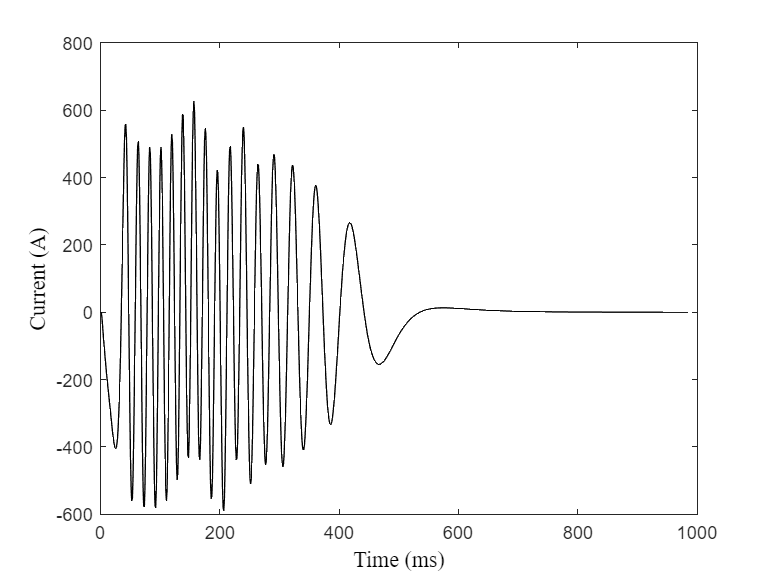

%grid on;

%-------------Phase A Rotor current----------------
figure 
plot(q1.i_ar, 'Color', 'black');
title(" ");
ylabel("Current (A)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
xlabel("Time (ms)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');

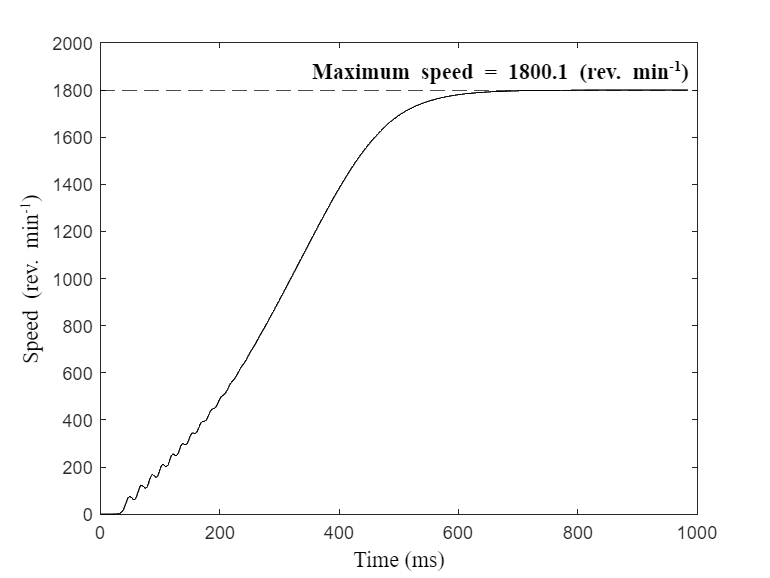

%grid on;

%---------Speed characteristics---------
figure
plot(q1.w_r, 'Color', 'black');
title(" ")
ylabel("Speed (rev. min^{-1})", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
xlabel("Time (ms)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
label2 = sprintf('Maximum speed = %0.1f (rev. min^{-1})', max_spd);
yline(max_spd, '--', 'label', label2, 'Color', 'black', 'FontSize', 12, 'FontName', 'Times', 'FontWeight','bold');

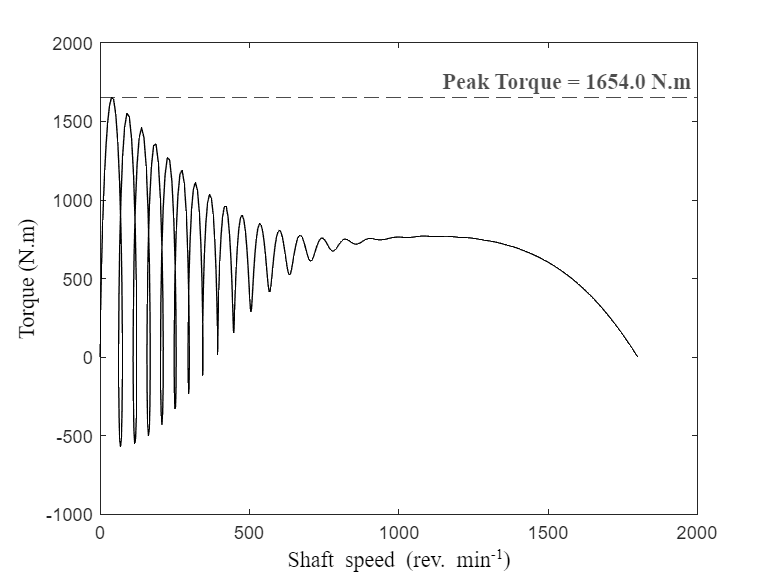

%grid on;

%---------Torque-speed characteristics---------
figure
plot(q1.w_r, q1.T_e, 'Color', 'black');
title(" ")
ylabel("Torque (N.m)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
xlabel("Shaft speed (rev. min^{-1})", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
label3 = sprintf('Peak Torque = %0.1f N.m', T_peak);
yline(T_peak, '--', 'label', label3, 'Color', 'black', 'FontSize', 12, 'FontName', 'Times', 'FontName', 'Times','FontWeight','bold');

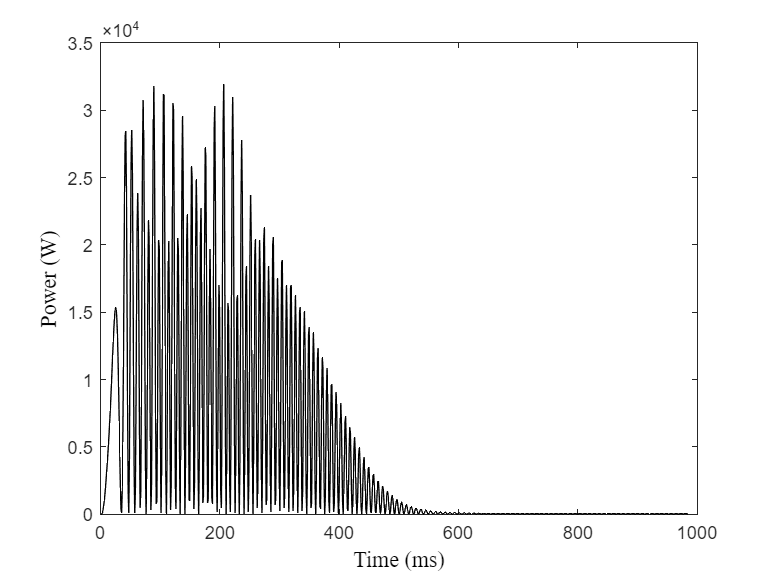

%grid on;

%----------Stator dissipation losses------------------
figure 
plot(q1.p_st_diss, 'Color', 'black');
title(" ");
ylabel("Power (W)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
xlabel("Time (ms)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');

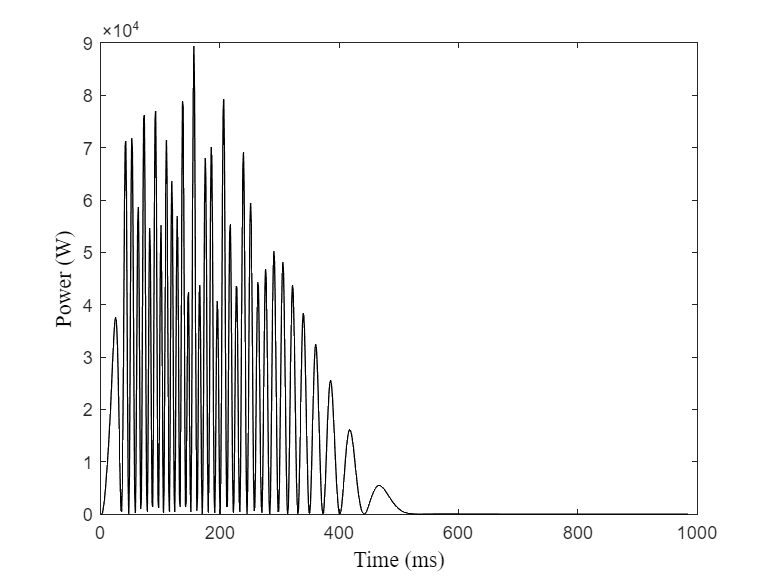

%grid on;

%----------Rotor dissipation losses------------------
figure 
plot(q1.p_rot_diss, 'Color', 'black');
title(" ");
ylabel("Power (W)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
xlabel("Time (ms)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');

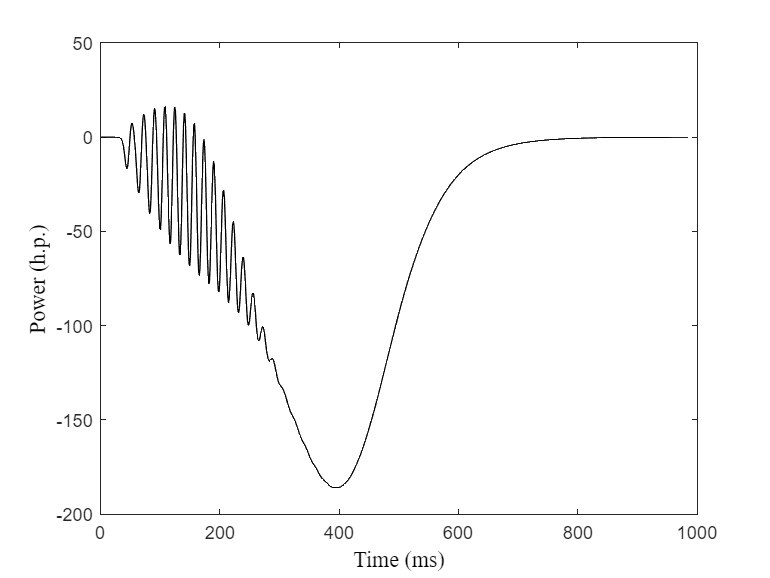

%grid on;

%---------Shaft power in horsepower---------
figure
plot(q1.hp, 'Color', 'black');
title(" ");
ylabel("Power (h.p.)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');
xlabel("Time (ms)", 'FontSize', 12, 'FontName', 'Times', 'Color', 'black');

%grid on;
